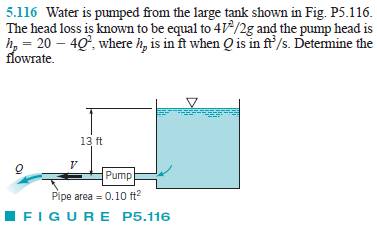

# constants

u = symunit;
gamma = 64.2*u.lbf/u.ft^3;
rho = 1.94*u.slug/u.f^3;
g = 32.2*u.ft/u.s^2;

# inflow properties

p1 = 0;
V1 = 0;
z1 = 13*u.ft;

# outflow properties

syms Q positive;
p2 = 0;
A2 = 0.10*u.ft^2;
V2(Q) = Q/A2;
z2 = 0;

# conservation of energy

hs(Q) = 20*u.ft-4*u.s^2/u.ft^5*Q^2;
hL = 4*V2^2/(2*g);
Q = solve(p2/gamma+V2^2/(2*g)+z2 == p1/gamma+V1^2/(2*g)+z1+hs-hL);
Q_vpa = vpa(Q, 3) %#ok

$$Q\_vpa = 1.67\,\frac{{\mathrm{ft}}^{3}}{s}$$

clear Q_vpa;
clearassum;